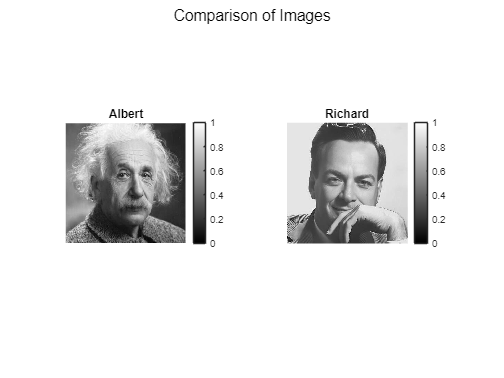

% Read the images
albert = imread('albert.jpg');
richard = imread('richard.jpg');

% Normalize both images to be in the range [0, 1]
albert = rescale(albert);   % marilyn / max(marilyn,[],'all' )
richard = rescale(richard);   % robert / max(robert,[],'all')

% Verify the two photos are of the same size
marilyn_size = size(albert);
robert_size = size(richard);

% Dimension of the squared images
N = size(richard, 1);

% Plot the two images side by side
figure;
subplot(1, 2, 1);
imshow(albert, []);
title('Albert');
colormap(gca, 'gray');
colorbar;

subplot(1, 2, 2);
imshow(richard, []);
title('Richard');
colormap(gca, 'gray');
colorbar;

sgtitle('Comparison of Images');

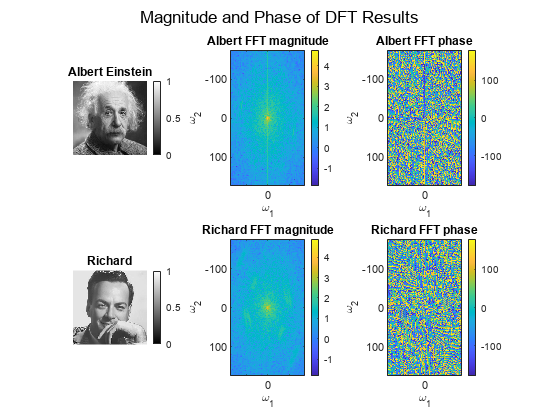


% Compute the 2D DFT of both images using FFT
FFT_marilyn = fft2(albert);
FFT_robert = fft2(richard);

% Plot the magnitude and phase of the FFT results
figure;

% Plot Marilyn Monroe
subplot(2, 3, 1);
imshow(albert, []);
title('Albert Einstein');
colorbar;

subplot(2, 3, 2);
imagesc(-N/2:N/2-1, -N/2:N/2-1, log10(abs(fftshift(FFT_marilyn))));
title('Albert FFT magnitude');
xlabel('\omega_1');
ylabel('\omega_2');
colorbar;

subplot(2, 3, 3);
imagesc(-N/2:N/2-1, -N/2:N/2-1, angle(fftshift(FFT_marilyn)) * 180 / pi);
title('Albert FFT phase');
xlabel('\omega_1');
ylabel('\omega_2');
colorbar;

% Plot Robert Oppenheimer
subplot(2, 3, 4);
imshow(richard, []);
title('Richard');
colorbar;

subplot(2, 3, 5);
imagesc(-N/2:N/2-1, -N/2:N/2-1, log10(abs(fftshift(FFT_robert))));
title('Richard FFT magnitude');
xlabel('\omega_1');
ylabel('\omega_2');
colorbar;

subplot(2, 3, 6);
imagesc(-N/2:N/2-1, -N/2:N/2-1, angle(fftshift(FFT_robert)) * 180 / pi);
title('Richard FFT phase');
xlabel('\omega_1');
ylabel('\omega_2');
colorbar;

sgtitle('Magnitude and Phase of DFT Results');

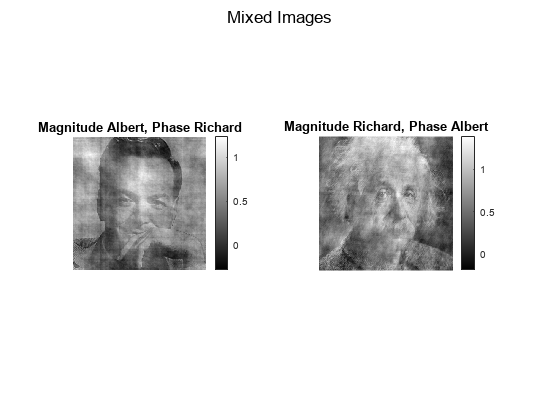


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% First 6 figure panel %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Reconstruct mixing between the photos
mm_pr = ifft2(abs(FFT_marilyn) .* exp(1i * angle(FFT_robert)));
mr_pm = ifft2(abs(FFT_robert) .* exp(1i * angle(FFT_marilyn)));

% Plot the mixed images
figure;

% Plot mixed image with magnitude of Marilyn and phase of Oppenheimer
subplot(1, 2, 1);
imshow(real(mm_pr), []);
title('Magnitude Albert, Phase Richard');
colorbar;

% Plot mixed image with magnitude of Oppenheimer and phase of Marilyn
subplot(1, 2, 2);
imshow(real(mr_pm), []);
title('Magnitude Richard, Phase Albert');
colorbar;

sgtitle('Mixed Images');


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Low pass Filter Part C




% Create subplots and plot original and low-pass filtered images
figure;

% Plot original images
subplot(2, 5, 1);
imshow(albert, []);
title('Original');
colormap(gca, 'gray');

subplot(2, 5, 6);
imshow(richard, []);
title('Original');
colormap(gca, 'gray');

% Plot low-pass filtered images with different cutoff frequencies
subplot(2, 5, 2);
imshow(image_low_pass_filter(FFT_marilyn, 5), []);

title('\omega_c = 5');
colormap(gca, 'gray');

subplot(2, 5, 3);
imshow(image_low_pass_filter(FFT_marilyn, 10), []);

title('\omega_c = 10');
colormap(gca, 'gray');

subplot(2, 5, 4);
imshow(image_low_pass_filter(FFT_marilyn, 20), []);

title('\omega_c = 20');
colormap(gca, 'gray');

subplot(2, 5, 5);
imshow(image_low_pass_filter(FFT_marilyn, 50), []);

title('\omega_c = 50');
colormap(gca, 'gray');

subplot(2, 5, 7);
imshow(image_low_pass_filter(FFT_robert, 5), []);

title('\omega_c = 5');
colormap(gca, 'gray');

subplot(2, 5, 8);
imshow(image_low_pass_filter(FFT_robert, 10), []);

title('\omega_c = 10');
colormap(gca, 'gray');

subplot(2, 5, 9);
imshow(image_low_pass_filter(FFT_robert, 20), []);

title('\omega_c = 20');
colormap(gca, 'gray');

subplot(2, 5, 10);
imshow(image_low_pass_filter(FFT_robert, 50), []);

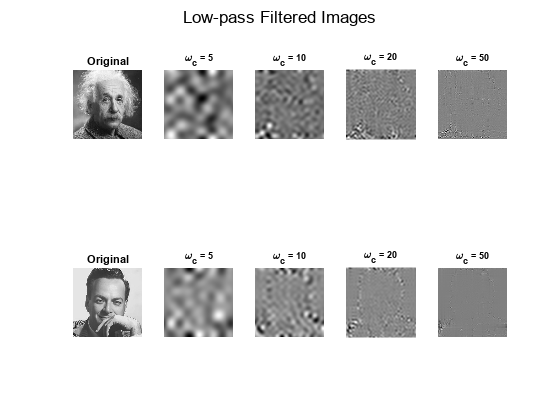

title('\omega_c = 50');
colormap(gca, 'gray');

% Adjust layout
sgtitle('Low-pass Filtered Images');

## Part d high pass

% Create subplots and plot original and high-pass filtered images
figure;

% Plot original images
subplot(2, 5, 1);
imshow(albert, []);
title('Original');
colormap(gca, 'gray');

subplot(2, 5, 6);
imshow(richard, []);
title('Original');
colormap(gca, 'gray');

% Plot high-pass filtered images with different cutoff frequencies
subplot(2, 5, 2);
imshow(image_high_pass_filter(FFT_marilyn, 5), []);

title('\omega_c = 5');
colormap(gca, 'gray');

subplot(2, 5, 3);
imshow(image_high_pass_filter(FFT_marilyn, 10), []);

title('\omega_c = 10');
colormap(gca, 'gray');

subplot(2, 5, 4);
imshow(image_high_pass_filter(FFT_marilyn, 20), []);

title('\omega_c = 20');
colormap(gca, 'gray');

subplot(2, 5, 5);
imshow(image_high_pass_filter(FFT_marilyn, 50), []);

title('\omega_c = 50');
colormap(gca, 'gray');

subplot(2, 5, 7);
imshow(image_high_pass_filter(FFT_robert, 5), []);

title('\omega_c = 5');
colormap(gca, 'gray');

subplot(2, 5, 8);
imshow(image_high_pass_filter(FFT_robert, 10), []);

title('\omega_c = 10');
colormap(gca, 'gray');

subplot(2, 5, 9);
imshow(image_high_pass_filter(FFT_robert, 20), []);

title('\omega_c = 20');
colormap(gca, 'gray');

subplot(2, 5, 10);
imshow(image_high_pass_filter(FFT_robert, 50), []);

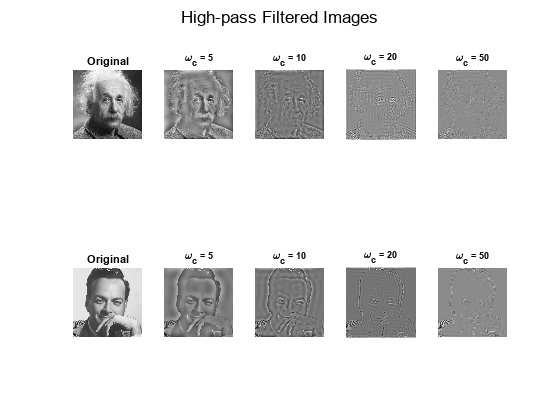

title('\omega_c = 50');
colormap(gca, 'gray');

% Adjust layout
sgtitle('High-pass Filtered Images');

## Convolution part e

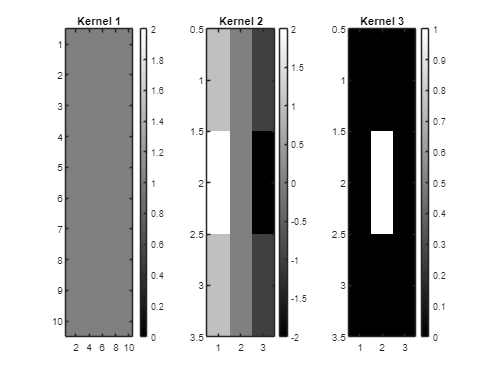

% Define kernels
kernel_1 = ones(10);  % All ones kernel
kernel_2 = [1, 0, -1; 2, 0, -2; 1, 0, -1];  % Sobel edge detection kernel
kernel_3 = [0, 0, 0; 0, 1, 0; 0, 0, 0];      % Identity kernel

% Plot kernels
figure;

% Kernel 1
subplot(1, 3, 1);
imagesc(kernel_1);
colormap(gca, 'gray');
title('Kernel 1');
colorbar;

% Kernel 2
subplot(1, 3, 2);
imagesc(kernel_2);
colormap(gca, 'gray');
title('Kernel 2');
colorbar;

% Kernel 3
subplot(1, 3, 3);
imagesc(kernel_3, [0, 1]); % Set color limits to [0, 1]
colormap(gca, 'gray');
title('Kernel 3');
colorbar;

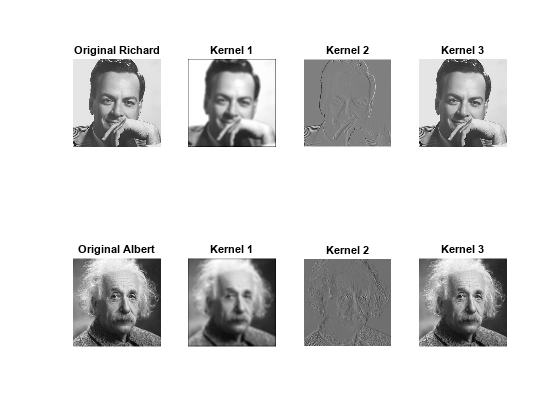


% Perform 2D convolution and plot the results
figure;

% Original images
subplot(2, 4, 1);
imshow(richard, []);
title('Original Richard');
colormap(gca, 'gray');

subplot(2, 4, 5);
imshow(albert, []);
title('Original Albert');
colormap(gca, 'gray');

% Convolution with kernel 1
subplot(2, 4, 2);
imshow(conv2(richard, kernel_1, 'same'), []);
title('Kernel 1');
colormap(gca, 'gray');

subplot(2, 4, 6);
imshow(conv2(albert, kernel_1, 'same'), []);
title('Kernel 1');
colormap(gca, 'gray');

% Convolution with kernel 2
subplot(2, 4, 3);
imshow(conv2(richard, kernel_2, 'same'), []);
title('Kernel 2');
colormap(gca, 'gray');

subplot(2, 4, 7);
imshow(conv2(albert, kernel_2, 'same'), []);
title('Kernel 2');
colormap(gca, 'gray');

% Convolution with kernel 3
subplot(2, 4, 4);
imshow(conv2(richard, kernel_3, 'same'), []);
title('Kernel 3');
colormap(gca, 'gray');

subplot(2, 4, 8);
imshow(conv2(albert, kernel_3, 'same'), []);
title('Kernel 3');
colormap(gca, 'gray');

## Functions

function filtered_image = image_low_pass_filter(image_fft, n)
    % Apply a low-pass filter
    N = size(image_fft, 1);
    FFT_lp = zeros(N, N);
    FFT_lp(N/2-n+1:N/2+n, N/2-n+1:N/2+n) = fftshift(image_fft(N/2-n+1:N/2+n, N/2-n+1:N/2+n));
    filtered_image = ifft2(ifftshift(FFT_lp));
end

function filtered_image = image_high_pass_filter(image_fft, n)
    % Apply a high-pass filter
    N = size(image_fft, 1);
    FFT_hp = fftshift(image_fft);
    FFT_hp(N/2-n+1:N/2+n, N/2-n+1:N/2+n) = 0;
    filtered_image = ifft2(ifftshift(FFT_hp));
end

